# I模型

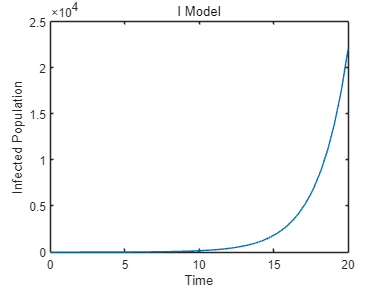

% 设置参数
i0 = 1;  % 初始感染人数
lambda = 0.5;  % 每天有效接触人数
tmax = 20;  % 模拟时间

% 求解模型
[t, i] = i_model(i0, lambda, tmax);

% 绘图
figure;
plot(t, i);
title('I Model');
xlabel('Time');
ylabel('Infected Population');

# SI模型

% 设置参数
i0 = 0.1; % 初始感染比例
lambda = 0.5; % 每天有效接触人数
tmax = 50; % 模拟时间

% 求解模型
[t, i] = si_model(i0, lambda, tmax);

% 找到 infected 和 susceptible 比例为 0.5 的时间点
infected_half = interp1(i, t, 0.5);
susceptible_half = interp1(1-i, t, 0.5);

% 绘图
figure;
plot(t, i, 'b', 'LineWidth', 2);
hold on;
plot(t, 1-i, 'r', 'LineWidth', 2);

% 标记 infected 和 susceptible 比例为 0.5 的点
plot(infected_half, 0.5, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
plot(susceptible_half, 0.5, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% 添加标记点的文本说明
text(infected_half, 0.55, ['t_mi = ', num2str(infected_half, '%.2f')], 'Color', 'b', 'HorizontalAlignment', 'right');
text(susceptible_half, 0.55, ['t_ms = ', num2str(susceptible_half, '%.2f')], 'Color', 'r', 'HorizontalAlignment', 'left');

title('SI Model');
xlabel('Time');
ylabel('Population Ratio');
legend('Infected', 'Susceptible', 'Location', 'north');

% 添加水平线以突出 0.5 比例
yline(0.5, '--k', 'LineWidth', 1);

% 计算传染病高峰时刻
tm = 1/lambda * log((1/i0) - 1);
disp(['Peak time: ', num2str(tm)]);

Peak time: 4.3944


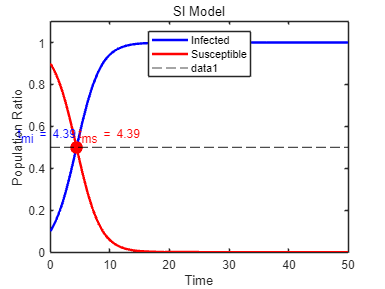


% 设置坐标轴范围，确保标记点可见
ylim([0 1.1]);

# SIS模型

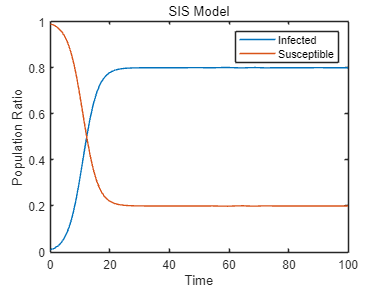

% 设置参数
i0 = 0.01;  % 初始感染比例
lambda = 0.5;  % 每天有效接触人数
mu = 0.1;  % 每天治愈比例
tmax = 100;  % 模拟时间

% 求解模型
[t, i] = sis_model(i0, lambda, mu, tmax);

% 绘图
figure;
plot(t, i);
hold on;
plot(t, 1-i);
title('SIS Model');
xlabel('Time');
ylabel('Population Ratio');
legend('Infected', 'Susceptible');


% 计算平衡点
equilibrium = 1 - mu/lambda;
disp(['Equilibrium point: ', num2str(equilibrium)]);

Equilibrium point: 0.8


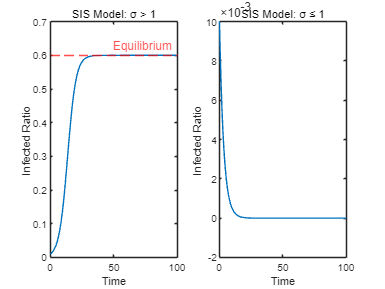


% 情况1: σ > 1
lambda1 = 0.5;
mu1 = 0.2;
[t1, i1] = sis_model(i0, lambda1, mu1, tmax);

% 情况2: σ ≤ 1
lambda2 = 0.2;
mu2 = 0.5;
[t2, i2] = sis_model(i0, lambda2, mu2, tmax);

% 绘图
figure;
subplot(1,2,1);
plot(t1, i1);
title('SIS Model: σ > 1');
xlabel('Time');
ylabel('Infected Ratio');
yline(1 - mu1/lambda1, '--r', 'Equilibrium');

subplot(1,2,2);
plot(t2, i2);
title('SIS Model: σ ≤ 1');
xlabel('Time');
ylabel('Infected Ratio');


% 显示R₀值
disp(['R₀ (Case 1): ', num2str(lambda1/mu1)]);

R₀ (Case 1): 2.5


disp(['R₀ (Case 2): ', num2str(lambda2/mu2)]);

R₀ (Case 2): 0.4


# SIR模型

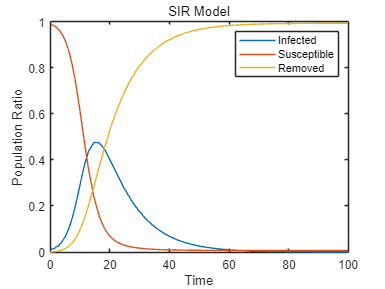

% 设置参数
i0 = 0.01;  % 初始感染比例
s0 = 0.99;  % 初始易感比例
lambda = 0.5;  % 每天有效接触人数
mu = 0.1;  % 每天治愈比例
tmax = 100;  % 模拟时间

% 求解模型
[t, y] = sir_model(i0, s0, lambda, mu, tmax);

% 绘图
figure;
plot(t, y);
title('SIR Model');
xlabel('Time');
ylabel('Population Ratio');
legend('Infected', 'Susceptible', 'Removed');

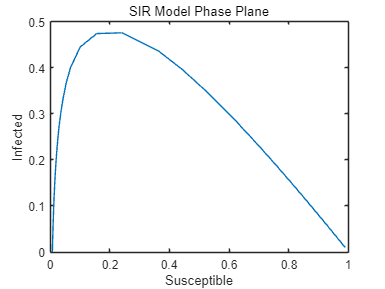


% 相平面图
figure;
plot(y(:,2), y(:,1));
title('SIR Model Phase Plane');
xlabel('Susceptible');
ylabel('Infected');


% 计算R0
R0 = lambda / mu;
disp(['R0: ', num2str(R0)]);

R0: 5
